clear
clc
syms A12 A21 xa AA BA CA AB BB CB PT t


A12=1.6383      %Constante A12 de la ecuación de Van Laar

A12 = 1.6383

A21=0.9419      %Constante A21 de la ecuación de Van Laar

A21 = 0.9419

AA=8.1122       %Constante A (de ecuación de Antoine) del compuesto A

AA = 8.1122

BA=1592.864     %Constante B (de ecuación de Antoine) del compuesto A

BA = 1.5929e+03

CA=226.184      %Constante C (de ecuación de Antoine) del compuesto A

CA = 226.1840

AB=8.0713       %Constante A (de ecuación de Antoine) del compuesto B

AB = 8.0713

BB=1730.63      %Constante B (de ecuación de Antoine) del compuesto B

BB = 1.7306e+03

CB=233.426      %Constante C (de ecuación de Antoine) del compuesto B

CB = 233.4260

PT=585          %Presión total (mmHg)

PT = 585

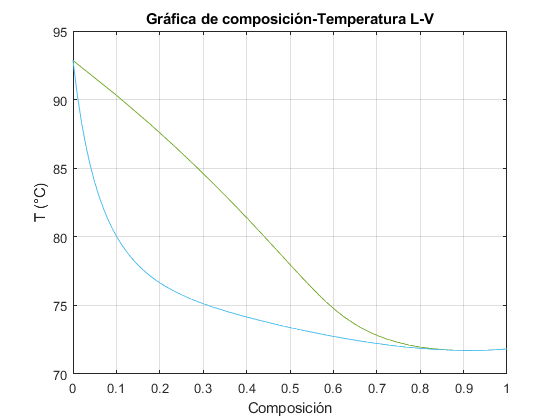

xa=linspace(0,1,100); %Fracción liquido del compuesto A

ga=exp(1).^(A12.*((1+(A12.*xa)./(A21*(1-xa))).^-2));
gb=exp(1).^(A21.*((1+(A21.*(1-xa))./(A12.*xa)).^-2));

T=zeros(1,100);
for i=1:1:100
    T(1,i)=vpasolve((ga(1,i)*10^(AA-BA/(CA+t))*xa(1,i))/PT+(gb(1,i)*10^(AB-BB/(CB+t))*(1-xa(1,i)))/PT==1,t);    
end


PA=10.^(AA-BA./(CA+T));
PB=10.^(AB-BB./(CB+T));
ya=(ga.*PA.*xa)./PT;


plot(ya,T)
hold on
plot(xa,T)
xlabel('Composición')
ylabel('T (°C)')
grid
title('Gráfica de composición-Temperatura L-V')